clear
clc
format long

m1=1;
m2=1;
l1=1; 
l2=1;
g=9.81;

y0=[pi;0;pi/2;0];

h=0.001;
tf=10;

%mit
%f = @(t,y) [y(2); (-g*(2*m1+m2)*sin(y(1))-m2*g*sin(y(1)-2*y(3))-2*sin(y(1)-y(3))*m2*((y(4)^2)*l2+(y(2)^2)*l1*cos(y(1)-y(3))))/(l1*(2*m1+m2-m2*cos(2*y(1)-2*y(3)))); y(4); (2*sin(y(1)-y(3))*((y(2)^2)*l1*(m1+m2)+g*(m1+m2)*cos(y(1))+(y(4)^2)*l2*m2*cos(y(1)-y(3))))/(l2*(2*m1+m2-m2*cos(2*y(1)-2*y(3))))];

%handout
f = @(t,y) [y(2); (-m2*cos(y(1)-y(3))*l1*(y(2)^2)*sin(y(1)-y(3))+m2*cos(y(1)-y(3))*g*sin(y(3))-m2*l2*(y(4)^2)*sin(y(1)-y(3))-(m1+m2)*g*sin(y(1)))/(l1*(m1+m2-m2*(cos(y(1)-y(3)))^2)) ; y(4); (m1+m2)*(l1*(y(2)^2)*sin(y(1)-y(3))+((y(4)^2)*sin(y(1)-y(3))*cos(y(1)-y(3))*m2*l2)/(m1+m2)+cos(y(1)-y(3))*g*sin(y(1))-g*sin(y(3)))/(l2*(m1+m2*(sin(y(1)-y(3)))^2))];

tspan=[0, tf];

tic
[t,y] = impliciteuler(f,tspan,y0,h);
toc

Elapsed time is 8.088991 seconds.


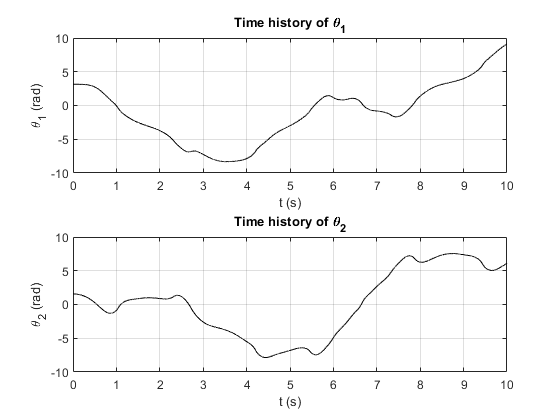


x1 = l1*sin(y(1,:));
y1=-l1*cos(y(1,:));
x2=x1+l2*sin(y(3,:));
y2=y1-l2*cos(y(3,:));

a=figure;
subplot(2,1,1);
plot(t,y(1,:),'k')
grid on
xlabel('t (s)')
ylabel('\theta_1 (rad)')
title('Time history of \theta_1')
subplot(2,1,2);
plot(t,y(3,:),'k')
grid on
xlabel('t (s)')
ylabel('\theta_2 (rad)')
title('Time history of \theta_2')
saveas(a,fullfile('C:\Users\lucam\MATLAB Drive\Published\Computing coursework\Grafici\Q4\Q4b','Q4b1.png'))

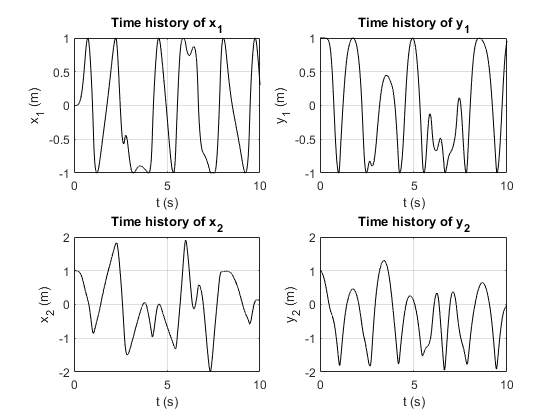


b=figure;
subplot(2,2,1);
plot(t,x1,'k')
grid on
xlabel('t (s)')
ylabel('x_1 (m)')
title('Time history of x_1')
subplot(2,2,2);
plot(t,y1,'k')
grid on
xlabel('t (s)')
ylabel('y_1 (m)')
title('Time history of y_1')
subplot(2,2,3);
plot(t,x2,'k')
grid on
xlabel('t (s)')
ylabel('x_2 (m)')
title('Time history of x_2')
subplot(2,2,4);
plot(t,y2,'k')
grid on
xlabel('t (s)')
ylabel('y_2 (m)')
title('Time history of y_2')
saveas(b,fullfile('C:\Users\lucam\MATLAB Drive\Published\Computing coursework\Grafici\Q4\Q4b','Q4b2.png'))

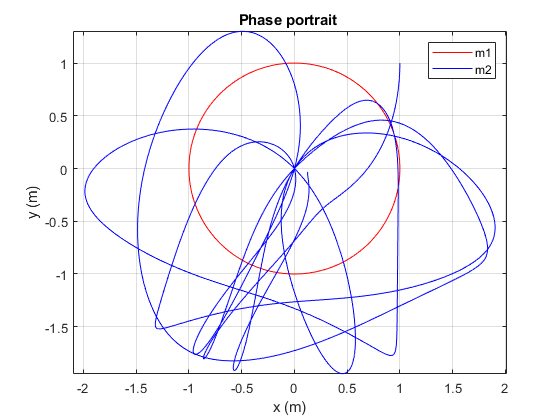


c=figure;
plot(x1,y1,'r')
grid on
axis equal
hold on
plot(x2,y2,'b')
xlabel('x (m)')
ylabel('y (m)')
title('Phase portrait ')
legend('m1','m2')
saveas(c,fullfile('C:\Users\lucam\MATLAB Drive\Published\Computing coursework\Grafici\Q4\Q4b','Q4b3.png'))

function [t,y] = impliciteuler(f,tspan,y0,h)
% Implicit Euler 

% Takes a function f, time span, initial condition and number of time step
% as input 

m = length(y0);
t = tspan(1):h:tspan(2); % Uniform grid 
N = length(t); % Number of grid points 
y = zeros(m,N); % Initialise variable representing numerical solution 
y(:,1) = y0; % Initial condition 



% This loop executes implicit Euler 
for i = 1:N-1
    f_alg = @(y_next) [y(:,i) + h*(f(t(i+1), y_next)) - y_next]; % The algebraic equation we have to solve at each time step 
    y_guess =y(:,i); 
    y(:,i+1) = fsolve(f_alg, y_guess, optimset('Display','off')); 
    %y(:,i+1) = y(:,i) + h*f(t(i),y(:,i));
end
end